# Using Casadi for Collision Avoidance OCP

Moving obstacle is implemented. The obstacle has a constant speed in [vx,vy,r]. r is yaw rate.

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

OCP = colliOCP();
OCP.build_basics();
OCP.add_control_bounds(); % use default bounds
OCP.add_initial_conditions(); % use default I.C.'s
OCP.add_path_constraints(); % use default constraints
OCP.add_ego_centers();
Xobs_init = [10,3,0];
% preset 1: 
% vx = -1; vy = 0; r = 0;
% preset 2: 
% vx = -1; vy = 0; r = 0.1;
% preset 3: 
vx = -1; vy = 0; r = 0.3;
[x_traj,y_traj,psi_traj] = OCP.make_const_v_trajectory(Xobs_init,vx,vy,r);
OCP.add_dynamic_obstacle_centers(x_traj,y_traj,psi_traj); % use dynamic obstacle
OCP.add_collision_constraint();
OCP.add_terminal_conditions(); % default T.C.'s
OCP.set_solver_init();
sol = OCP.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:      585
Number of nonzeros in inequality constraint Jacobian.:      608
Number of nonzeros in Lagrangian Hessian.............:      505

Total number of variables............................:      165
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      105
Total number of inequality constraints...............:      293
        inequality constraints with only lower bounds:      190
   inequality constraints with lower and upper bounds:      102
        inequality constraints with only upper bounds:        1

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

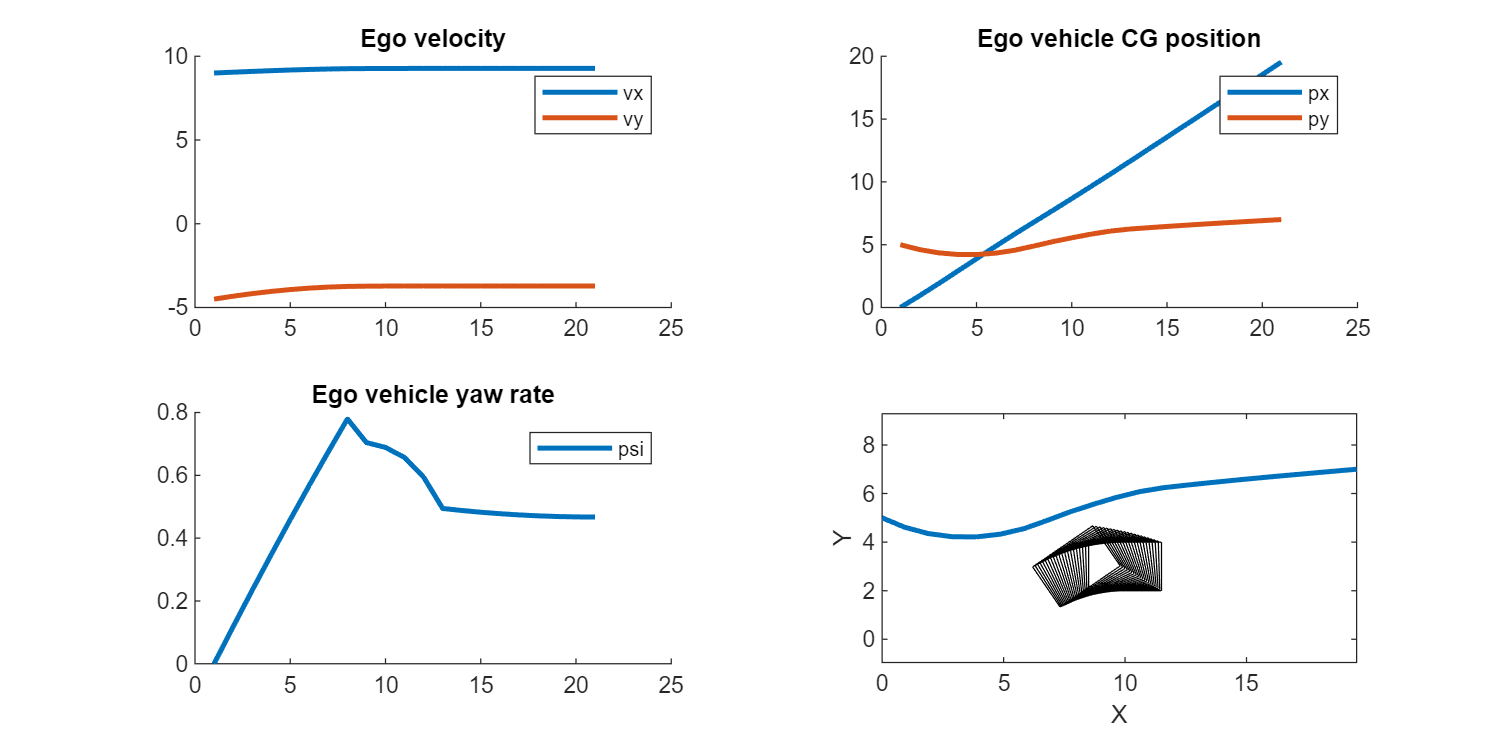

basic_plots(OCP,sol);

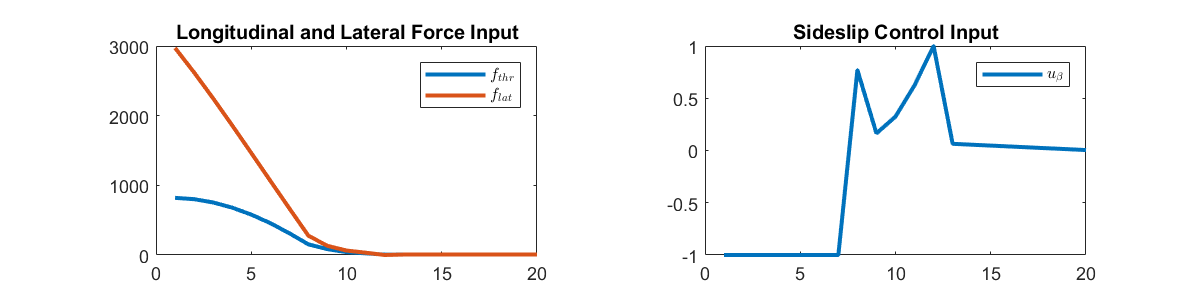

controls_plot(OCP,sol);

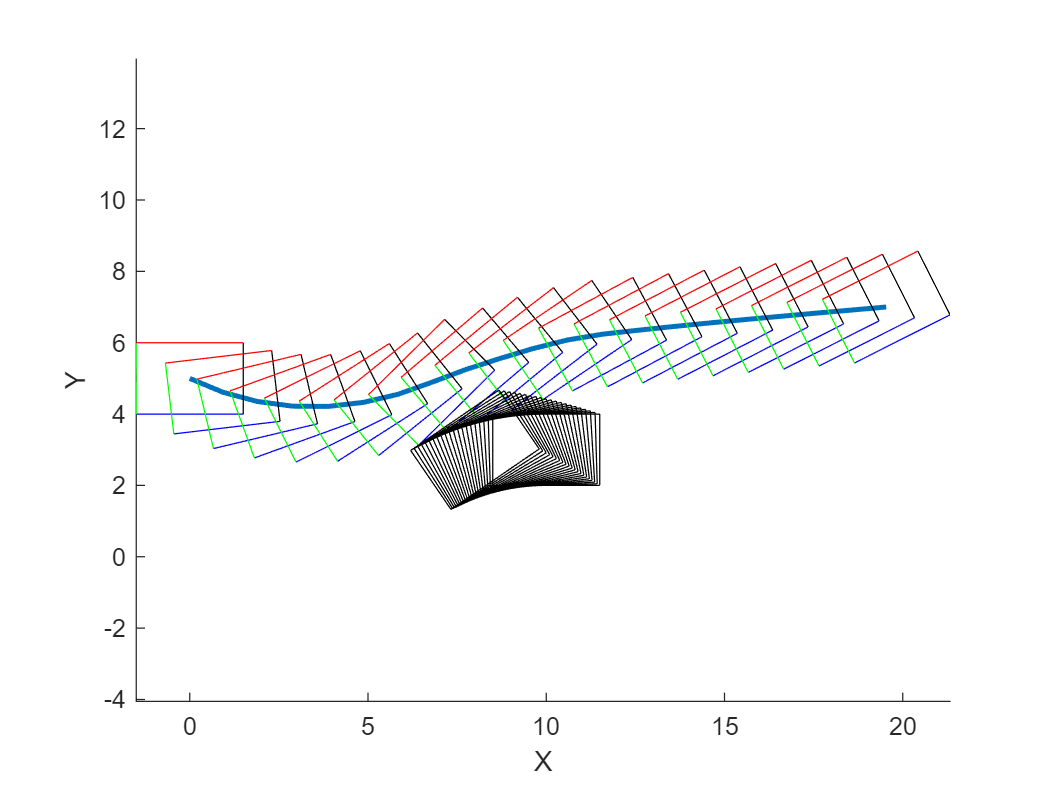

% overlap the vehicle body frame by frame onto the results
rectangle_overlap(OCP,sol);

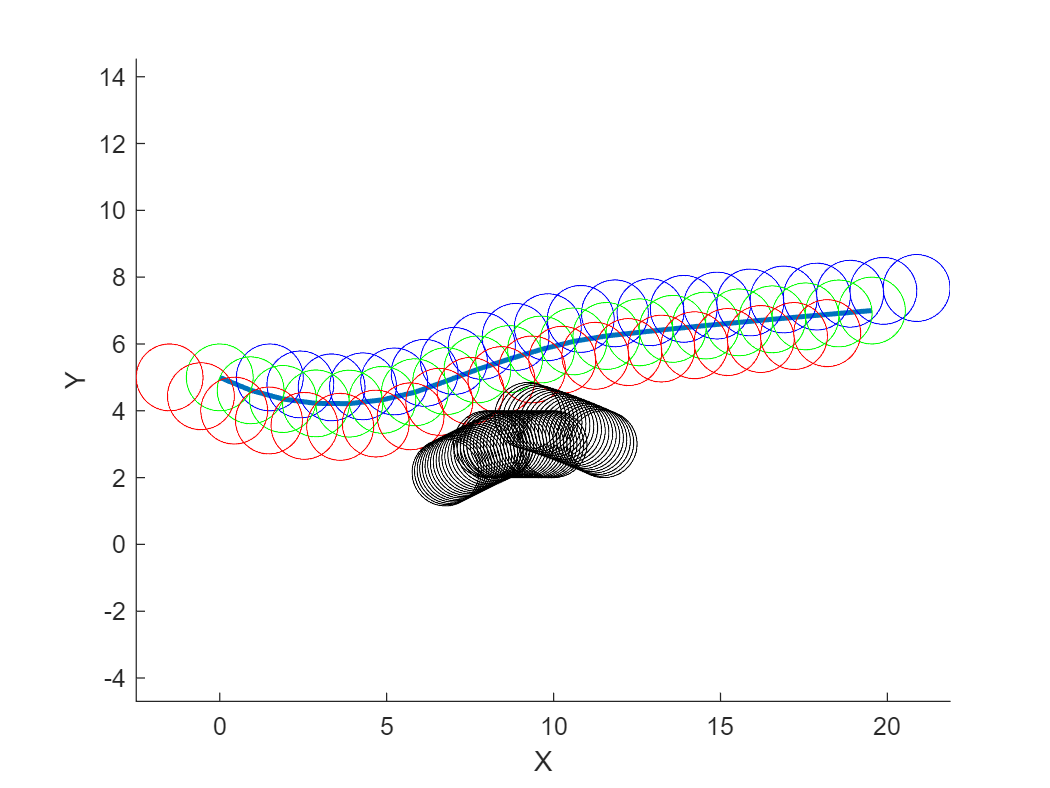

% overlap the vehicle three-circle representation frame-by-frame onto the
% results
circles_overlap(OCP,sol);

Make a video frame by frame, rectangle shape

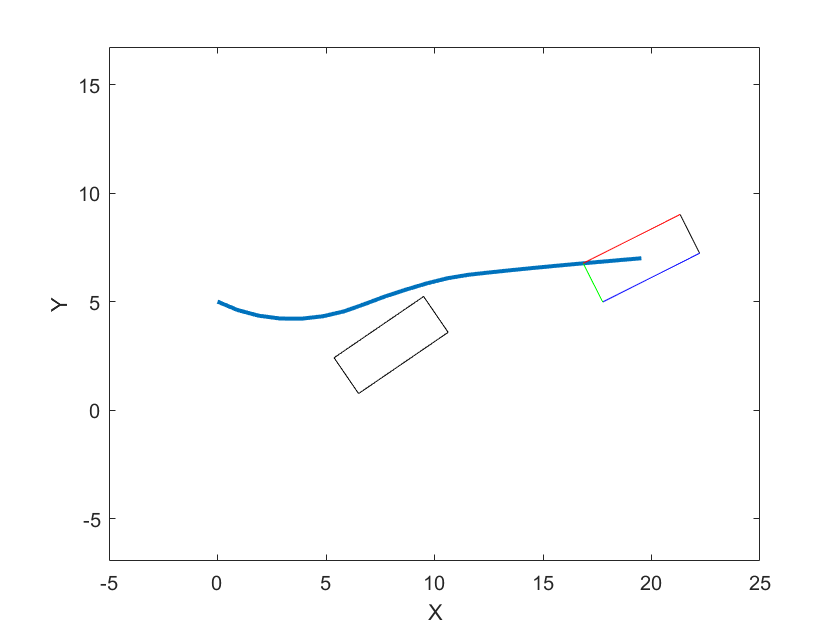

videoName = 'preset3';
make_video_rectangles(OCP,sol,videoName);

Make a video frame by frame, Ziegler 3-circle shape

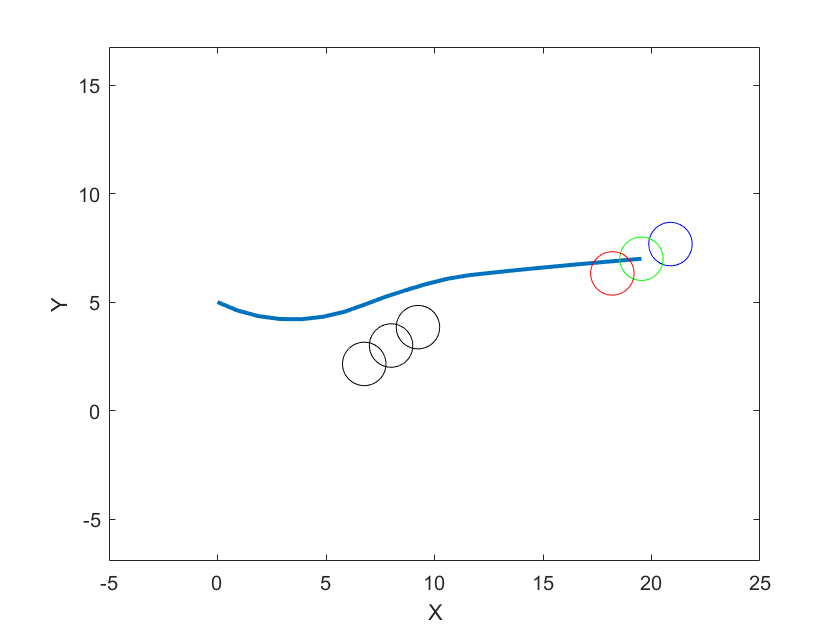

videoName = 'preset3_circ';
make_video_circles(OCP,sol,videoName);

SNAPSHOTS

% static obstacle comparison

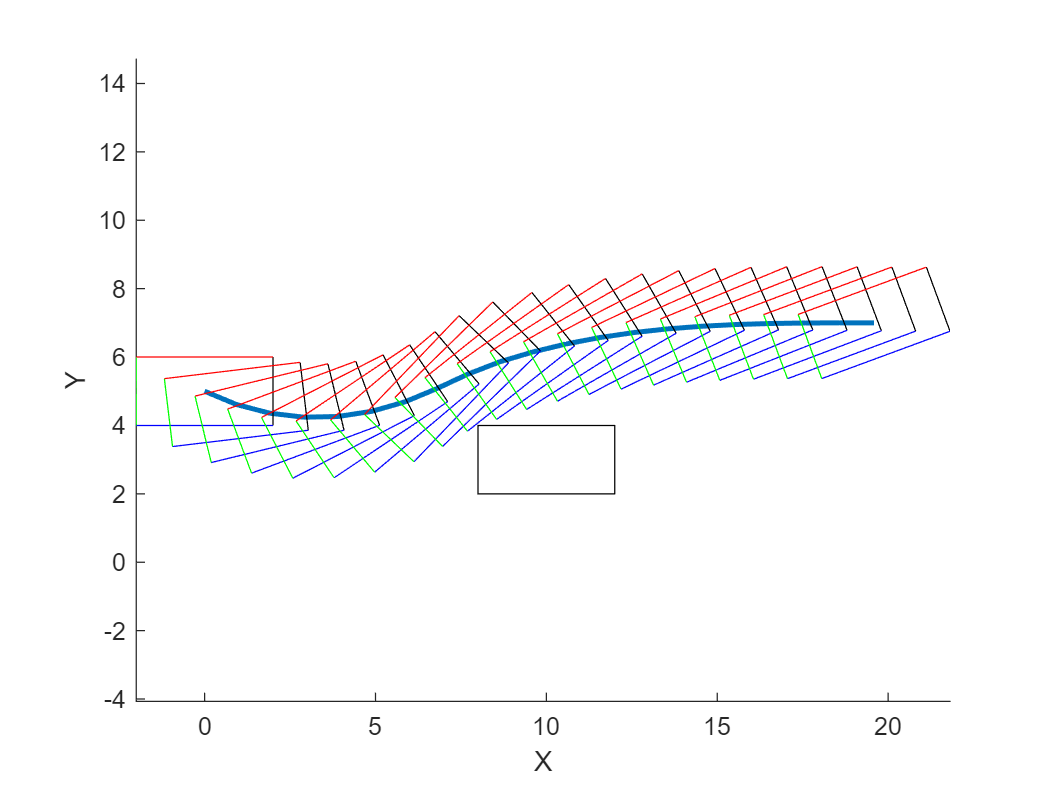

% moving obstacle

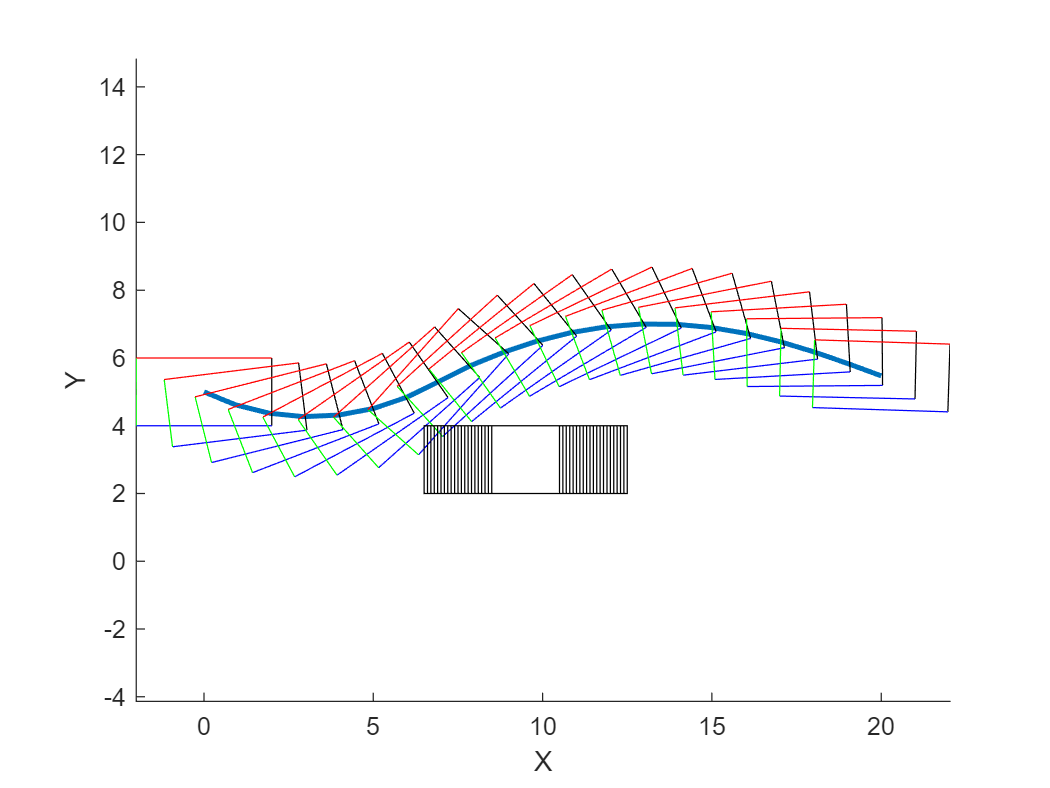

% moving and spinning obstacle (preset 2 vx=-1, vy=0, r=0.1)

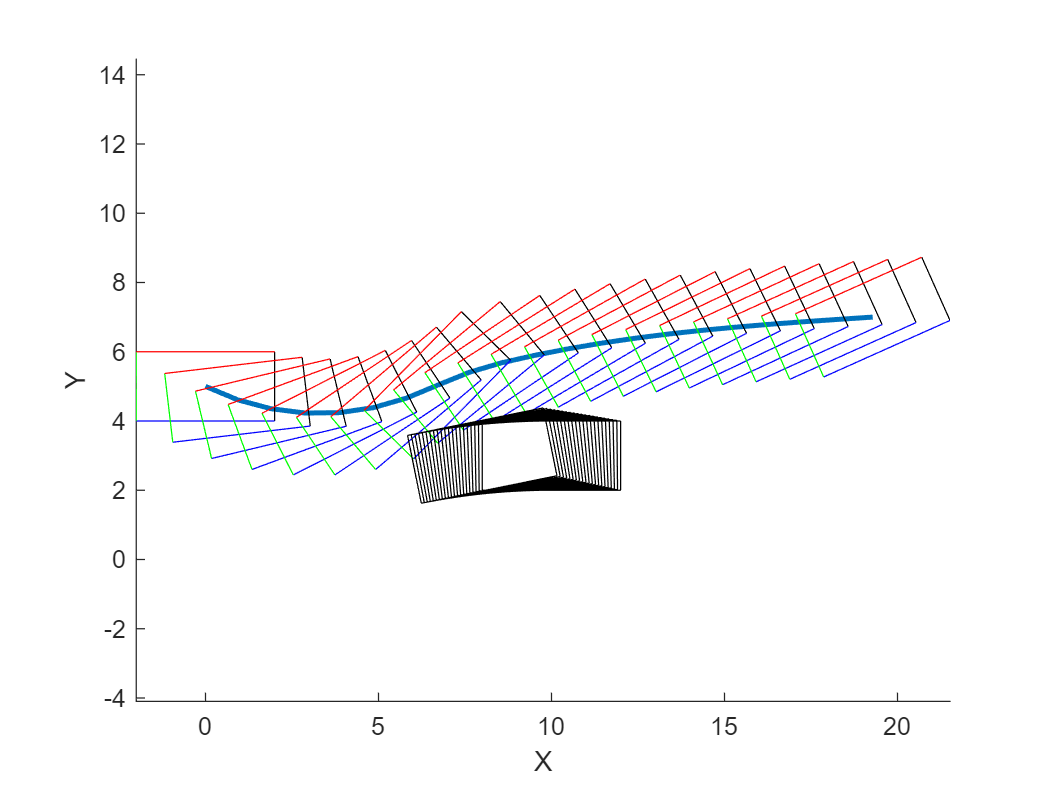

% moving and spinning obstacle (preset 3 vx=-1, vy=0, r=0.3)

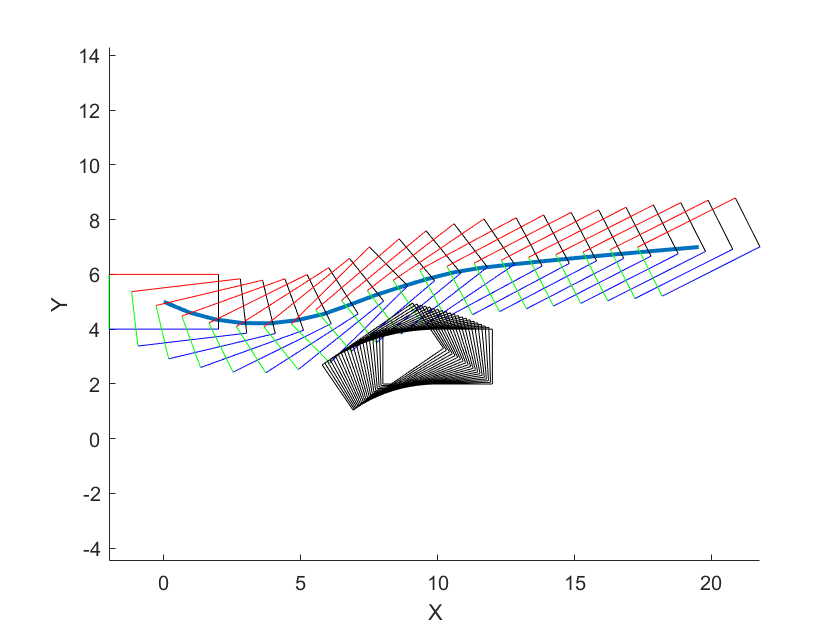

Helper functions (you may want to group these helper functions into a class later)

function ClearLinesFromAxes()
  axesHandlesToChildObjects = findobj(gca, 'Type', 'line');
  if ~isempty(axesHandlesToChildObjects)
    delete(axesHandlesToChildObjects);
  end  
end

function basic_plots(OCP,sol)
    %basic_plots Plot the basic system states
    figure('Position',[100 100 800 400]);
    tiledlayout(2,2)
    nexttile;
    hold on
    plot(sol.value(OCP.vx),'LineWidth',2);
    plot(sol.value(OCP.vy),'LineWidth',2);
    legend('vx','vy');
    title('Ego velocity')
    nexttile;
    hold on
    plot(sol.value(OCP.px),'LineWidth',2);
    plot(sol.value(OCP.py),'LineWidth',2);
    legend('px','py')
    title('Ego vehicle CG position');
    nexttile;
    hold on
    plot(sol.value(OCP.psi),'LineWidth',2);
    legend('psi')
    title('Ego vehicle yaw rate')
    nexttile;
    plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
    xlabel('X'); ylabel('Y')
    obs_colors = zeros(4,3); % obstacle color: all black
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    for i = 1:length(OCP.px_obs)
        drawVehicleBox(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a+OCP.b,OCP.R_col,obs_colors);
    end
end

function controls_plot(OCP,sol)
    %controls_plot Plot the control signals
    figure('Position',[100 100 800 200])
    tiledlayout(1,2);
    nexttile
    plot(sol.value(OCP.f_thr),'LineWidth',2);
    hold on;
    plot(sol.value(OCP.f_lat),'LineWidth',2);
    title('Longitudinal and Lateral Force Input');
    legend('$f_{thr}$','$f_{lat}$','interpreter','latex')
    nexttile;
    plot(sol.value(OCP.u_beta),'LineWidth',2);
    legend('$u_{\beta}$','interpreter','latex');
    title('Sideslip Control Input');
end

function rectangle_overlap(OCP,sol)
    %rectangle_overlap Draw the ego-obstacle vehicles rectangles in overlap

    hFigure = figure();
    hold on;
    plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    
    obs_colors = zeros(4,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        drawVehicleBox(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a+OCP.b,OCP.R_col);
        drawVehicleBox(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a+OCP.b,OCP.R_col,obs_colors);
    end
    
    xlabel('X'); ylabel('Y')
    axis equal
end

function make_video_rectangles(OCP,sol,videoName)
    %make_video_rectangles Make a video with the name videoName
    %   make_video_rectangles(OCP,sol,videoName)
    v = VideoWriter([videoName '.avi']);
    v.FrameRate = 10;
    open(v);
    hFigure = figure();
    hold on;
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    
    obs_colors = zeros(4,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
        hold on;
        drawVehicleBox(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a+OCP.b+OCP.R_col,OCP.R_col);
        drawVehicleBox(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a+OCP.b+OCP.R_col,OCP.R_col,obs_colors);
    
        xlim([-5, 25]);
        ylim([-5, 15]);
        xlabel('X'); ylabel('Y')
        axis equal;
        frame = getframe(hFigure);
        writeVideo(v,frame);
        hold off;
        %ClearLinesFromAxes(); % delete all line objects
    end
    close(v);
end

function circles_overlap(OCP,sol)
    %circles_overlap Draw the ego-obstacle vehicles Ziegler 3-circles in overlap
    hFigure = figure();
    hold on;
    plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    
    obs_colors = zeros(3,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        drawVehicleCircles(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a,OCP.R_col/2);
        drawVehicleCircles(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a,OCP.R_col/2,obs_colors);
    end
    
    xlabel('X'); ylabel('Y')
    axis equal
end

function make_video_circles(OCP,sol,videoName)
    %make_video_circles Make a video with the name videoName
    %   make_video_circles(OCP,sol,videoName)
    v = VideoWriter([videoName '.avi']);
    v.FrameRate = 10;
    open(v);
    hFigure = figure();
    hold on;
    X_c_arr = sol.value(OCP.px);
    Y_c_arr = sol.value(OCP.py);
    psi_arr = sol.value(OCP.psi);
    Xobs_c_arr = sol.value(OCP.px_obs);
    Yobs_c_arr = sol.value(OCP.py_obs);
    psiobs_c_arr = sol.value(OCP.psi_obs);
    
    obs_colors = zeros(4,3); % obstacle color: all black
    for i = 1:length(sol.value(OCP.px))
        plot(sol.value(OCP.px),sol.value(OCP.py),'LineWidth',2);
        hold on;
        drawVehicleCircles(X_c_arr(i),Y_c_arr(i),psi_arr(i),OCP.a,OCP.R_col/2);
        drawVehicleCircles(Xobs_c_arr(i),Yobs_c_arr(i),psiobs_c_arr(i),OCP.a,OCP.R_col/2,obs_colors);  
        xlim([-5, 25]);
        ylim([-5, 15]);
        xlabel('X'); ylabel('Y')
        axis equal;
        frame = getframe(hFigure);
        writeVideo(v,frame);
        hold off;
        %ClearLinesFromAxes(); % delete all line objects
    end 
    close(v);
end